# Neuropil gain analysis

% whole field NP, with all soma (responsive and unresponsive), removed
addpath('456_1 flfl','458_2 flfl','458_3 flfl','458_5 flfl','468_1 flfl','456_2 tecta flfl','458_1 tecta flfl','460_2 tecta flfl','460_3 tecta flfl','460_5 tecta flfl','460_6 tecta flfl','472_2 flfl','472_1 flfl','480_2 tecta flfl','480_3 flfl','486_1 flfl','488_1 tecta flfl','487_2 tecta flfl','487_1 flfl')

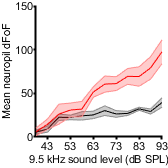

% 9.5 kHz neuropil gain - control
con1 = load('C1-20211015 exp467 mouse 1 tmem16flfl 9_5 khz gain 6 rep 10-70 db atten_neuroPil.mat'); 
con1.numLevels = size(con1.neuroPF,2);

con2 = load('C1-20211217 exp486 mouse 1 tmem16aflfl 9_5 khz gain R IC 10-70 db atten 190deep_neuroPil.mat'); 
con2.numLevels = size(con2.neuroPF,2);

con3 = load('C1-exp458 m2 flfl 9_5 khz 4 rep 10-70 db atten 5 db steps R IC 3_neuroPil.mat');
con3.numLevels = size(con3.neuroPF,2);
con3.numROI = size(con3.allROI,2);

con4 = load('C1-exp458 m3 flfl 9_5 khz 6 rep 10-60 db atten 5 db steps L IC_neuroPil.mat');
con4.numLevels = size(con4.neuroPF,2);
con4.neuroPF(9).max = NaN;

con5 = load('C1-20211103 exp472 mouse 1 tmem16aflfl 9.5 khz gain 10-70 6 rep_neuroPil.mat');
con5.numLevels = size(con5.neuroPF,2);

cko1 = load('C1-exp458 m1 tecta flfl 9_5 khz 4 rep 10-70 db atten 5 db steps_neuroPil.mat');
cko1.numLevels = size(cko1.neuroPF,2);

cko2 = load('C1-20211229 exp488 mouse 1 tmem16aflfl 9.5 khz gain 10-70db atten 6reps_neuroPil.mat');
cko2.numLevels = size(cko2.neuroPF,2);

cko3 = load('C1-20211220 exp487 mouse2 tecta tmem16aflfl 9.5 khz gain 10-70 db atten R IC 170_neuroPil.mat');
cko3.numLevels = size(cko3.neuroPF,2);

cko4 = load('C1-exp460 mouse5 L IC tecta flfl 9_5 khz 6 rep 10-60 db atten 5 db steps_neuroPil.mat');
cko4.numLevels = size(cko4.neuroPF,2);
cko4.numROI = size(cko4.allROI,2);

cko5 = load('C1-exp460 mouse2 tecta flfl 9_5 khz 4 rep 10-70 db atten 5 db steps_neuroPil.mat');
cko5.numLevels = size(cko5.neuroPF,2);
cko5.numROI = size(cko5.allROI,2);

cko6 = load('C1-exp456 m2 9_5khz 10-60 db 5 db steps 6 reps 2x later_neuroPil.mat');
cko6.numLevels = size(cko6.neuroPF,2);
cko6.numROI = size(cko6.allROI,2);

conMeanMatx = [];
for y = 1:11
    con9khzmean(y) = nanmean([con1.neuroPF(y).max,con2.neuroPF(y).max,con3.neuroPF(y).max,con4.neuroPF(y).max,con5.neuroPF(y).max]);
    conMeanMatx = [conMeanMatx;[con1.neuroPF(y).max,con2.neuroPF(y).max,con3.neuroPF(y).max,con4.neuroPF(y).max,con5.neuroPF(y).max]];
    con9khzSEM(y) = nanstd([con1.neuroPF(y).max,con2.neuroPF(y).max,con3.neuroPF(y).max,con4.neuroPF(y).max,con5.neuroPF(y).max])/sqrt(5);
end
for y = 12:13
    con9khzmean(y) = nanmean([con1.neuroPF(y).max,con2.neuroPF(y).max,con3.neuroPF(y).max,con5.neuroPF(y).max]);
   % conMeanMatx = [conMeanMatx;[con1.mean(y),con2.mean(y),NaN,con4.mean(y),con5.mean(y),NaN]];
    con9khzSEM(y) = nanstd([con1.neuroPF(y).max,con2.neuroPF(y).max,con3.neuroPF(y).max,con5.neuroPF(y).max])/sqrt(4);
end
ckoMeanMatx = [];
for y = 1:11
    cko9khzmean(y) = nanmean([cko1.neuroPF(y).max,cko2.neuroPF(y).max,cko3.neuroPF(y).max,cko4.neuroPF(y).max,cko5.neuroPF(y).max,cko6.neuroPF(y).max]);
    ckoMeanMatx = [ckoMeanMatx;[cko1.neuroPF(y).max,cko2.neuroPF(y).max,cko3.neuroPF(y).max,cko4.neuroPF(y).max,cko5.neuroPF(y).max,cko6.neuroPF(y).max]];
    cko9khzSEM(y) = nanstd([cko1.neuroPF(y).max,cko2.neuroPF(y).max,cko3.neuroPF(y).max,cko4.neuroPF(y).max,cko5.neuroPF(y).max,cko6.neuroPF(y).max])/sqrt(6);   
end
for y = 12:13
    cko9khzmean(y) = nanmean([cko1.neuroPF(y).max,cko2.neuroPF(y).max,cko3.neuroPF(y).max,cko5.neuroPF(y).max]);
    %ckoMeanMatx = [ckoMeanMatx;[NaN,cko2.mean(y),NaN,cko4.mean(y),cko5.mean(y),cko6.mean(y)]];
    cko9khzSEM(y) = nanstd([cko1.neuroPF(y).max,cko2.neuroPF(y).max,cko3.neuroPF(y).max,cko5.neuroPF(y).max])/sqrt(4);
end

figure
shadedErrorBar([con2.numLevels:-1:1],con9khzmean*100,con9khzSEM*100)
hold on
shadedErrorBar([con2.numLevels:-1:1],cko9khzmean*100,cko9khzSEM*100,'lineprops','r')
ylabel('Mean neuropil dFoF')
xlabel('9.5 kHz sound level (dB SPL)')
xticks([1 3 5 7 9 11 13])
xticklabels({'33','43','53','63','73','83','93'})
figQuality(gcf,gca,[1.75 1.75])
xlim([2 13])
ylim([0 150])

% print(gcf,'-dpdf')

% linear model - by mouse

genoBasecon = {'con','con','con','con','con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'};

geno = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]';
mousecon = {'M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5'};
mousecko = {'M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12'};
mouse = [mousecon,mousecko]';
locationBase = {'1' '2','3','4','5','6','7','8','9','10','11'}; 
location = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase]';
byMouse = [[con1.neuroPF(1:11).max],[con2.neuroPF(1:11).max],[con3.neuroPF(1:11).max],[con4.neuroPF(1:11).max],[con5.neuroPF(1:11).max],[cko1.neuroPF(1:11).max],[cko2.neuroPF(1:11).max],[cko3.neuroPF(1:11).max],[cko4.neuroPF(1:11).max],[cko5.neuroPF(1:11).max],[cko6.neuroPF(1:11).max]]';

tbl = table(geno,mouse,location,byMouse,'VariableNames',{'Genotype','Mouse','Location','BW'})

tbl = 121×4 table
    Genotype    Mouse     Location       BW   
    ________    ______    ________    ________

    {'con'}     {'M1'}     {'1' }      0.51684
    {'con'}     {'M1'}     {'2' }      0.31191
    {'con'}     {'M1'}     {'3' }      0.33763
    {'con'}     {'M1'}     {'4' }      0.26196
    {'con'}     {'M1'}     {'5' }      0.18909
    {'con'}     {'M1'}     {'6' }      0.14704
    {'con'}     {'M1'}     {'7' }     0.098727
    {'con'}     {'M1'}     {'8' }      0.11047
    {'con'}     {'M1'}     {'9' }      0.19721
    {'con'}     {'M1'}     {'10'}      0.14437
    {'con'}     {'M1'}     {'11'}     0.045778
    {'con'}     {'M2'}     {'1' }      0.37774
    {'con'}     {'M2'}     {'2' }      0.22205
    {'con'}     {'M2'}     {'3' }      0.30533
    {'con'}     {'M2'}     {'4' }      0.29324
    {'con'}     {'M2'}     {'5' }      0.26605

lme = fitlme(tbl,'BW~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml') 

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations             120
    Fixed effects coefficients           2
    Random effects coefficients         22
    Covariance parameters                3

Formula:
    BW ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -25.103    -11.249    17.551           -35.103 

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE          tStat     DF     pValue        Lower      Upper  
    {'(Intercept)' }        0.25951     0.074993    3.4605    118    0.00075132    0.11101    0.40802
    {'Genotype_cko'}        0.27889     0.076681     3.637    118    0.00041026    0.12704    0.43074

Random effects covariance parameters (95% CIs):
Group: Location (11 Levels)
    Name1                  Name2                 

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta =     0.2595
    0.2789


betanames = 2×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE          tStat     DF        pValue       Lower      Upper  
    {'(Intercept)' }        0.25951     0.074993    3.4605    17.153    0.0029571     0.1014    0.41763
    {'Genotype_cko'}        0.27889     0.076681     3.637     9.032    0.0053943    0.10552    0.45226


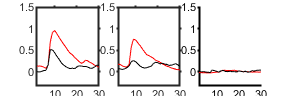


% show some example traces

figure;

subplot(1,3,1)
plot(cko3.neuroPF(1).dFoF,'r');
hold on
plot(con1.neuroPF(1).dFoF,'k');
ylim([-0.3 1.5])
xlim([2 30])
subplot(1,3,2)
plot(cko3.neuroPF(4).dFoF,'r');
hold on
plot(con1.neuroPF(4).dFoF,'k');
ylim([-0.3 1.5])
xlim([2 30])
subplot(1,3,3)
plot(cko3.neuroPF(11).dFoF,'r');
hold on
plot(con1.neuroPF(11).dFoF,'k');
ylim([-0.3 1.5])
xlim([2 30])
figQuality(gcf,gca,[3,1])

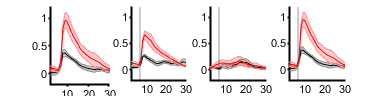


% Show mean trace
time = [1:1:32];
meanCon90 = mean([con1.neuroPF(1).dFoF;con2.neuroPF(1).dFoF;con3.neuroPF(1).dFoF;con4.neuroPF(1).dFoF;con5.neuroPF(1).dFoF]);
stdCon90 = std([con1.neuroPF(1).dFoF;con2.neuroPF(1).dFoF;con3.neuroPF(1).dFoF;con4.neuroPF(1).dFoF;con5.neuroPF(1).dFoF])/sqrt(5);
meanCko90 = mean([cko1.neuroPF(1).dFoF;cko2.neuroPF(1).dFoF;cko3.neuroPF(1).dFoF;cko4.neuroPF(1).dFoF;cko5.neuroPF(1).dFoF;cko6.neuroPF(1).dFoF;]);
stdCko90 = std([cko1.neuroPF(1).dFoF;cko2.neuroPF(1).dFoF;cko3.neuroPF(1).dFoF;cko4.neuroPF(1).dFoF;cko5.neuroPF(1).dFoF;cko6.neuroPF(1).dFoF;])/sqrt(6);
meanCon70 = mean([con1.neuroPF(4).dFoF;con2.neuroPF(4).dFoF;con3.neuroPF(4).dFoF;con4.neuroPF(4).dFoF;con5.neuroPF(4).dFoF]);
stdCon70 = std([con1.neuroPF(4).dFoF;con2.neuroPF(4).dFoF;con3.neuroPF(4).dFoF;con4.neuroPF(4).dFoF;con5.neuroPF(4).dFoF])/sqrt(5);
meanCko70 = mean([cko1.neuroPF(4).dFoF;cko2.neuroPF(4).dFoF;cko3.neuroPF(4).dFoF;cko4.neuroPF(4).dFoF;cko5.neuroPF(4).dFoF;cko6.neuroPF(4).dFoF;]);
stdCko70 = std([cko1.neuroPF(4).dFoF;cko2.neuroPF(4).dFoF;cko3.neuroPF(4).dFoF;cko4.neuroPF(4).dFoF;cko5.neuroPF(4).dFoF;cko6.neuroPF(4).dFoF;])/sqrt(6);

meanCon40 = mean([con1.neuroPF(11).dFoF;con2.neuroPF(11).dFoF;con3.neuroPF(11).dFoF;con4.neuroPF(11).dFoF;con5.neuroPF(11).dFoF]);
stdCon40 = std([con1.neuroPF(11).dFoF;con2.neuroPF(11).dFoF;con3.neuroPF(11).dFoF;con4.neuroPF(11).dFoF;con5.neuroPF(11).dFoF])/sqrt(5);
meanCko40 = mean([cko1.neuroPF(11).dFoF;cko2.neuroPF(11).dFoF;cko3.neuroPF(11).dFoF;cko4.neuroPF(11).dFoF;cko5.neuroPF(11).dFoF;cko6.neuroPF(11).dFoF;]);
stdCko40 = std([cko1.neuroPF(11).dFoF;cko2.neuroPF(11).dFoF;cko3.neuroPF(11).dFoF;cko4.neuroPF(11).dFoF;cko5.neuroPF(11).dFoF;cko6.neuroPF(11).dFoF;])/sqrt(6);


figure
subplot(1,4,1)
shadedErrorBar(time,meanCon90,stdCon90)
hold on
shadedErrorBar(time,meanCko90,stdCko90,'lineprops','r')
ylim([-0.2 1.2])
xlim([2 30])
figQuality(gcf,gca,[4,1])
subplot(1,4,2)
shadedErrorBar(time,meanCon70,stdCon70)
hold on
shadedErrorBar(time,meanCko70,stdCko70,'lineprops','r')
patch([6 6 7 7], [1.2 -0.2 -0.2 1.2],'k','EdgeColor','none','FaceAlpha',0.2);
ylim([-0.2 1.2])
xlim([2 30])
figQuality(gcf,gca,[4,1])
subplot(1,4,3)
shadedErrorBar(time,meanCon40,stdCon40)
hold on
shadedErrorBar(time,meanCko40,stdCko40,'lineprops','r')
patch([6 6 7 7], [1.2 -0.2 -0.2 1.2],'k','EdgeColor','none','FaceAlpha',0.2);
ylim([-0.2 1.2])
xlim([2 30])
figQuality(gcf,gca,[4,1])
subplot(1,4,4)
shadedErrorBar(time,meanCon90,stdCon90)
hold on
shadedErrorBar(time,meanCko90,stdCko90,'lineprops','r')
ylim([-0.2 1.2])
xlim([2 30])
patch([6 6 7 7], [1.2 -0.2 -0.2 1.2],'k','EdgeColor','none','FaceAlpha',0.2);
figQuality(gcf,gca,[4,1])

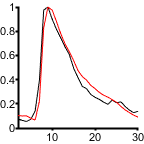

%print(gcf,'-dpdf')


% normalized
figure;
plot(meanCon90/max(meanCon90),'k')
hold on
plot(meanCko90/max(meanCko90),'r')
xlim([2 30])
figQuality(gcf,gca,[1.5,1.5])

%print(gcf,'-dpdf')

% display NP images

[fname pname] = uigetfile({'*.tif';'*.TIF';'*.tiff';'*.TIFF'},'select the still video tiff file');
imData = loadTif([pname fname], 8);

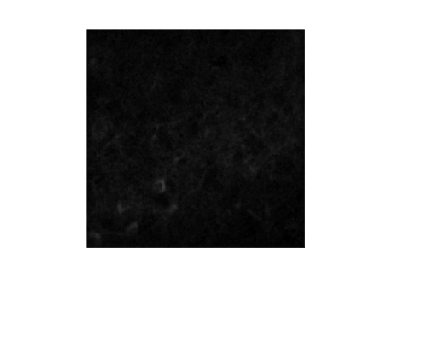

h =   Image with properties:

           CData: [256×256 uint8]
    CDataMapping: 'scaled'

  Show all properties


h = imshow(imData)

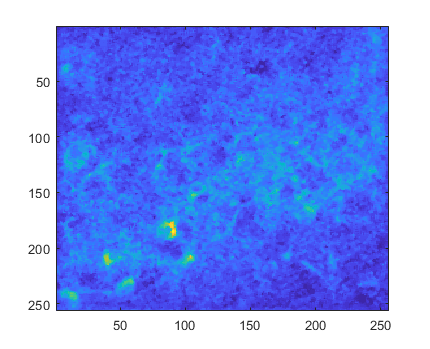

h =   Image with properties:

           CData: [256×256 double]
    CDataMapping: 'scaled'

  Show all properties


imData2 = double(imData);
h = imagesc(imData2)

figure;
hold on;
image = ones(256,256)

image =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

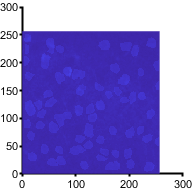

for x = 1:cko4.numROI   
    % plot ROI 
    image = image - (cko4.allROI{1,x});
end
for j = 1:256
    for k = 1:256
        if image(j,k) < 0
            image(j,k) = 1;
        end
    end
end
colormap gray
imagesc(image)
figQuality(gcf,gca, [2 2])


figure;
hold on;
image = ones(256,256)
for x = 1:con3.numROI   
    % plot ROI 
    image = image - (con3.allROI{1,x});
end
colormap gray
imagesc(image)
figQuality(gcf,gca, [2 2])


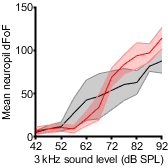

% 3 kHz neuropil 

addpath('480_3 flfl','483_3 flfl','486_1 flfl','483_2 tecta flfl','484_2 tecta flfl','486_3 flfl','486_4 tecta flfl','487_2 tecta flfl','488_1 tecta flfl');

cko1 = load('C1-20211229 exp488 mouse 1 tmem16aflfl 3 khz gain 10-60db atten 4reps L IC_neuroPil.mat');
cko1.numLevels = size(cko1.neuroPF,2);

cko2 = load('C1-20211220 exp487 mouse2 tecta tmem16aflfl 3 khz gain 10-60 db atten R IC 170_neuroPil.mat');
cko2.numLevels = size(cko2.neuroPF,2);

cko3 = load('C1-20211217 exp486 mouse 4 tecta tmem16aflfl 3 khz  gain R IC 10-60 db atten 150umdeep_neuroPil.mat');
cko4 = load('C1-20211214 exp484 mouse2 tecta tmem16flfl 3 khz gain 10-60 db 5 db steps 6 rep_neuroPil.mat');
cko5 = load('C1-20211211 exp483 mouse 2 tecta tmem16a flfl 3 khz gain 10-60 db 5 db steps R IC 150 um_neuroPil.mat');
con1 = load('C1-20211217 exp486 mouse 1 tmem16aflfl 3 khz gain R IC 10-70 db atten 190deep_neuroPil.mat');
con1.numLevels = size(con1.neuroPF,2);

con2 = load('C1-20211217 exp486 mouse 3 tmem16aflfl 3 khz gain 10-60 db 5 db steps 6 reps_neuroPil.mat');
con2.numLevels = size(con2.neuroPF,2);

con3 = load('C1-20211211 exp483 mouse 3 tmem16a flfl 3 khz gain 10-60 db 5 db steps R IC 150 um_neuroPil.mat');
con4 = load('C1-20211119 exp480 mouse 3  tmem16aflfl 3 khz gain R ic 10-60 db 5 db steps_neuroPil.mat');

for y = 1:11
    con9khzmean(y) = nanmean([con1.neuroPF(y).max,con2.neuroPF(y).max,con3.neuroPF(y).max,con4.neuroPF(y).max]);
    %conMeanMatx = [conMeanMatx;[con1.max(y),con2.max(y)]];
    con9khzSEM(y) = nanstd([con1.neuroPF(y).max,con2.neuroPF(y).max,con3.neuroPF(y).max,con4.neuroPF(y).max])/sqrt(4);
end

ckoMeanMatx = [];
for y = 1:11
    cko9khzmean(y) = nanmean([cko1.neuroPF(y).max,cko2.neuroPF(y).max,cko3.neuroPF(y).max,cko4.neuroPF(y).max,cko5.neuroPF(y).max]);
    %ckoMeanMatx = [ckoMeanMatx;[cko1.mean(y),cko2.mean(y),cko3.mean(y),cko4.mean(y),cko5.mean(y),cko6.mean(y)]];
    cko9khzSEM(y) = nanstd([cko1.neuroPF(y).max,cko2.neuroPF(y).max,cko3.neuroPF(y).max,cko4.neuroPF(y).max,cko5.neuroPF(y).max])/sqrt(5);   
end


figure
shadedErrorBar([con2.numLevels:-1:1],con9khzmean*100,con9khzSEM*100)
hold on
shadedErrorBar([con2.numLevels:-1:1],cko9khzmean*100,cko9khzSEM*100,'lineprops','r')
ylabel('Mean neuropil dFoF')
xlabel('3 kHz sound level (dB SPL)')
xticks([1 3 5 7 9 11])
xticklabels({'42','52','62','72','82','92'})
figQuality(gcf,gca,[1.75 1.75])
xlim([1 11])
ylim([0 150])
 %print(gcf,'-dpdf')


genoBasecon = {'con','con','con','con','con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'};

geno = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]';
mousecon = {'M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4'};
mousecko = {'M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M7','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11'};
mouse = [mousecon,mousecko]';
locationBase = {'1' '2','3','4','5','6','7','8','9','10','11'}; 
location = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase]';
byMouse = [[con1.neuroPF(1:11).max],[con2.neuroPF(1:11).max],[con3.neuroPF(1:11).max],[con4.neuroPF(1:11).max],[cko1.neuroPF(1:11).max],[cko2.neuroPF(1:11).max],[cko3.neuroPF(1:11).max],[cko4.neuroPF(1:11).max],[cko5.neuroPF(1:11).max]]';

tbl = table(geno,mouse,location,byMouse,'VariableNames',{'Genotype','Mouse','Location','BW'})

tbl = 99×4 table
    Genotype    Mouse     Location        BW    
    ________    ______    ________    __________

    {'con'}     {'M1'}     {'1' }        0.48675
    {'con'}     {'M1'}     {'2' }         0.6692
    {'con'}     {'M1'}     {'3' }        0.28612
    {'con'}     {'M1'}     {'4' }        0.10518
    {'con'}     {'M1'}     {'5' }       0.010884
    {'con'}     {'M1'}     {'6' }     -0.0028977
    {'con'}     {'M1'}     {'7' }        0.11459
    {'con'}     {'M1'}     {'8' }      0.0076735
    {'con'}     {'M1'}     {'9' }       0.058961
    {'con'}     {'M1'}     {'10'}      -0.019129
    {'con'}     {'M1'}     {'11'}       0.033474
    {'con'}     {'M2'}     {'1' }        0.87654
    {'con'}     {'M2'}     {'2' }        0.78698
    {'con'}     {'M2'}     {'3' }        0.56537
    {'con'}     {'M2'}     {'4' }        0.64559
    {'con'}  

lme = fitlme(tbl,'BW~Genotype+(1|Location)+(1|Mouse)') 

lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations              99
    Fixed effects coefficients           2
    Random effects coefficients         20
    Covariance parameters                3

Formula:
    BW ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC      LogLikelihood    Deviance
    38.445    51.42    -14.222          28.445  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat      DF    pValue       Lower      Upper  
    {'(Intercept)' }         0.44613    0.12998     3.4322    97    0.0008814    0.18815     0.7041
    {'Genotype_cko'}        0.054198    0.11125    0.48719    97      0.62723    -0.1666    0.27499

Random effects covariance parameters (95% CIs):
Group: Location (11 Levels)
    Name1                  Name2                  Type         